clc; close all; clear all;
s = tf('s');
P = exp(-0.4*s)/(s-0.1)/s;
Ts = 0.02;

0.4/Ts % <---- verifica Ts para que la division see entero

ans = 20


PNDz = c2d(P,Ts,'zoh')

PNDz =
 
            0.0002001 z + 0.0002003
  z^(-20) * -----------------------
             z^2 - 2.002 z + 1.002
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


PNDz = absorbDelay(PNDz);
Gss = ss(PNDz)

Gss =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10     x11     x12     x13     x14     x15     x16     x17     x18     x19     x20     x21     x22
   x1    2.002  -1.002       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0
   x2        1       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0
   x3        0       1       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0
   x4        0       0       1       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0
   x5        0       0       0       1       0       0       0       0

A = Gss.A;
B = Gss.B;
C = Gss.C;
D = Gss.D

D = 0

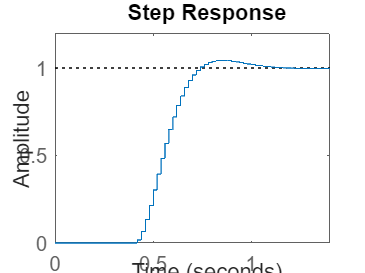


Qy = 1000;
Q = C'*Qy*C;
R = 0.1;

K = dlqr(A,B,Q,R);
nx = size(A,1);

Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;
step(ss(A-B*K,B*Kr,C-D*K,D*Kr,Ts))